clear

NUM_BIT = 6;
STD = 2*9.0E-4

STD = 0.0018

% 蒙特卡洛次数
N = 10^4;

unit_mis = 1+STD*randn(N, 2^NUM_BIT);
% 算法矫正
unit_CF = ADCPackage.CF(unit_mis);
unit_recombine_8 = ADCPackage.Recombine_xlayer(unit_mis,8);
unit_recombine_16 = ADCPackage.Recombine_xlayer(unit_mis,16);

% 计算失配
code = [0 : (2^NUM_BIT-1)]';

code_bin = ADCPackage.int2bin(code, NUM_BIT);

decoder = zeros(NUM_BIT, 2^NUM_BIT);
for i = 1:NUM_BIT
    decoder(i,(2^(i-1)+1):2^i) = 1;
end

code_array = code_bin(:, 1:NUM_BIT)*decoder;

INL_mis_nrm = unit_mis*code_array'./sum(unit_mis, 2)-code'./2^NUM_BIT;
INL_CF_nrm = unit_CF*code_array'./sum(unit_mis, 2)-code'./2^NUM_BIT;
INL_rcmb8_nrm = unit_recombine_8*code_array'./sum(unit_mis, 2)-code'./2^NUM_BIT;
INL_rcmb16_nrm = unit_recombine_16*code_array'./sum(unit_mis, 2)-code'./2^NUM_BIT;

% INL分位点
p = 99.7

p = 99.7000

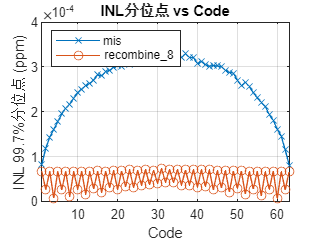


figure
plot(code, prctile(abs(INL_mis_nrm), p),'-x');
hold on
plot(code, prctile(abs(INL_rcmb8_nrm), p),'-o');
legend('mis','recombine\_8', "Location", 'northwest')
grid on;

xlabel('Code')
ylabel(['INL ',num2str(p),'%分位点 (ppm)'])
title('INL分位点 vs Code')

xlim([code(2), code(end)])